tic
b=1

b = 1

a=[1 -0.9]

a =     1.0000   -0.9000


n=-5:50

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44


[x1,x1n]=unitseq(-5,50,0)

x1 = 1×56 logical array
   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


x1n =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44


[x2,x2n]=unitseq(-5,50,-10)

x2 = 1×56 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


x2n =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44


[x,xn]=sigadd(x1,x1n,-x2,x2n)

x =      0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


xn =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44


y=filter(b,a,x)

y =          0         0         0         0         0    1.0000    1.9000    2.7100    3.4390    4.0951    4.6856    5.2170    5.6953    6.1258    6.5132    5.8619    5.2757    4.7481    4.2733    3.8460    3.4614    3.1153    2.8037    2.5234    2.2710    2.0439    1.8395    1.6556    1.4900    1.3410    1.2069    1.0862    0.9776    0.8798    0.7919    0.7127    0.6414    0.5773    0.5195    0.4676    0.4208    0.3787    0.3409    0.3068    0.2761    0.2485    0.2236    0.2013    0.1812    0.1630


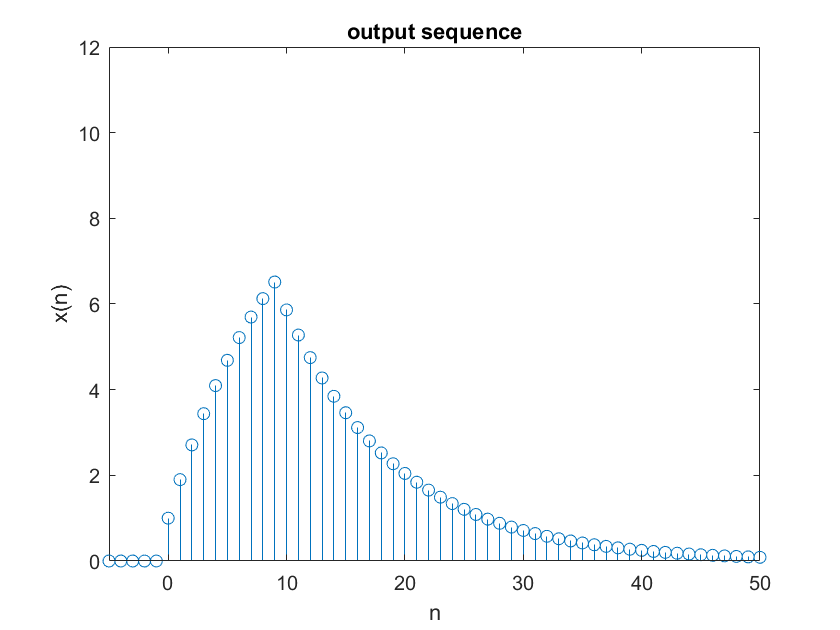

stem(xn,y)
title('output sequence')
xlabel('n')
ylabel('x(n)')
axis tight
axis ([n(1) n(end) 0 12])

h=sum(abs(impz(b,a,n)))

h = 9.9536

z=abs(roots(a))

z = 0.9000

if z<1
    disp('The system is stable')
else
    error('The system is unstable')
end

The system is stable


toc

Elapsed time is 0.301490 seconds.
